# TP Simulation du Rover : Modélisation des moteurs à courant continu (MCC) et implémentation d'un correcteur PI

## Modélisation du MCC

Le Rover possède 4 MCC identiques à celui présenté sur l'image :

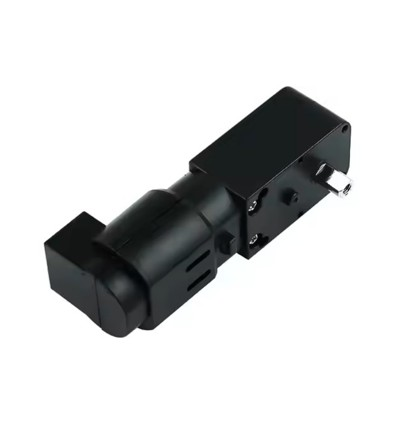

Pour commander ce MCC et faire en sorte qu'il soit capable de respecter la vitesse de sortie indiquée malgré des potentielles perturbations (irrégularités du sol, glissement, vibrations, etc.), il faut commencer par le modéliser.

Le modèle d'un MCC se compose en deux partie : la partie électrique et la partie mécanique.

### Modèle électrique du moteur

Commençons par modéliser la partie électrique.

Voici le schéma électrique permettant de modéliser le MCC :

***Question 1 : Utilisez la loi des mailles pour déterminer l'équation électique du MCC***


$$e\left(t\right)+R\;i\left(t\right)+p\;L\frac{\mathrm{d}}{\mathrm{d}t}i\left(t\right)-u\left(t\right)=0$$


***Question 2 : Appliquez la transformée de Laplace sur l'équation obtenue***


$$U\left(p\right)=E\left(p\right)+I\left(p\right)\left(R+p\;L\right)$$


***Question 3 : En déduire la fonction de transfert ***${\textrm{FT}}_{\textrm{elec}} \left(p\right)=\frac{I\left(p\right)}{U\left(p\right)-E\left(p\right)}$*** en fonction de ***$R,L$*** et ***$p$


$${\textrm{FT}}_{\textrm{elec}} \left(p\right)=\frac{1}{R+p\;L}$$


### Modèle mécanique du moteur

Maintenant, étudions la partie mécanique du moteur :

L'application du principe fondamental de la dynamique sur l'arbre moteur donne l'équation suivante :


$$c_m \left(t\right)-f\ldotp \omega_m \left(t\right)=J\ldotp \frac{\mathrm{d}}{\mathrm{d}t}\omega_m \left(t\right)$$


avec $c_m \left(t\right)$ le couple moteur, $c_v \left(t\right)=f\ldotp \omega_m \left(t\right)$ le couple de frottements visqueux.

Dans un premier temps, le couple de frottements secs $c_f$ est négligé. Par conséquent, il n'apparaît pas dans l'équation mécanique.

***Question 4 :  Appliquez la transformée de Laplace sur l'équation mécanique du moteur***


$$C_m \left(p\right)-f\Omega_m \left(p\right)=p\;J\;\Omega_m \left(p\right)$$


***Question 5 : Calculez la fonction de transfert ***${\textrm{FT}}_{\textrm{méca}} \left(p\right)=\frac{\Omega_m \left(p\right)}{C_m \left(p\right)}$


$${\textrm{FT}}_{\textrm{méca}} \left(p\right)=\frac{1}{f+p\;J}$$


### Lien entre les équations mécaniques et électriques du moteur

Les relations suivantes permettent de faire le lien entre les équations mécaniques et électriques du moteur :


$$e\left(t\right)=K_e \ldotp \omega_m \left(t\right)$$



$$c_m \left(t\right)=K_t \ldotp i\left(t\right)$$


avec $K_t$ la constante de couple et $K_e$ la constante de force électromotrice.

***Question 5 : Appliquez la transformée de Laplace sur ces deux équations***


$$E\left(p\right)=K_e \Omega_m \left(p\right)$$



$$C_m \left(p\right)=K_t I\left(p\right)$$


### Modélisation par schéma blocs

Maintenant que vous avez écrit les 4 équations du moteur à courant continu dans le domaine de Laplace, on peut le représenter sous la forme d'un schéma blocs.

Les paramètres du moteur sont les suivants :

- Résistance de l'induit du MCC : $R=5,45\;\Omega$

- Inductance de l'induit : $L=0,5\;\textrm{mH}$

- Inertie équivalente de l'ensemble moteur + roue : $J=4,5\ldotp {10}^{-7} \;\textrm{kg}\ldotp m^2$

- Coefficient de frottement visqueux : $f=2\ldotp {10}^{-7} \;N\ldotp m\ldotp s^{-1}$

- Constante de force electromotrice : $K_e =3,3\ldotp {10}^{-3} \;V\ldotp {\textrm{rad}}^{-1} \ldotp s$

- Constante de couple : $K_t =3,3\ldotp {10}^{-3} \;N\ldotp m\ldotp A^{-1}$

***Question 6 : Définissez ces variables dans le code MATLAB ci-dessous en respectant les unités SI***

clear; % vide le workspace avant l'execution du code

% Définissez vos variables ici
R = 5.45;
L = 0.5e-3;
J = 4.5e-7;
f = 2e-7;
Ke = 3.3e-3;
Kt = 3.3e-3;

 Le schéma blocs ci-dessous représente le modèle du moteur à courant continu sans le réducteur :

***Question 7 : En utilisant les équations dans le domaine de Laplace calculées dans les questions 3,4 et 5, reproduisez et complétez le schéma blocs ci-dessus dans Simulink. Les blocs Simulink nécessaires pour reproduire ce schéma sont les blocs : "step", "transfer fcn", "gain" et "scope", enregistrez le fichier dans votre dossier de travail avec le nom "MCC_model.slx".***

Comme mentionné dans le TP précédent, le moteur est alimenté grâce à une commande PWM (Pulse Width Modulation). Dans le code Python implémenté sur le vrai robot, on envoie une commande "control_motor_pwm(pwm_value)" pour faire tourner les moteurs à une certaine vitesse. La valeur "pwm_value" que l'on envoie varie entre -2000 et 2000. Ces valeurs correspondent quasiement linéairement à la tension d'alimentation u. Une valeur de pwm_value = 0 correspond à une tension u de 0V (le moteur est à l'arrêt) et une valeur de pwm_value = 2000 correspond à une tension u de 7,34V (moteur à la vitesse max).

La courbe de la tension u en fonction de la valeur de la commande pwm mesurée sur le vrai moteur est la suivante :

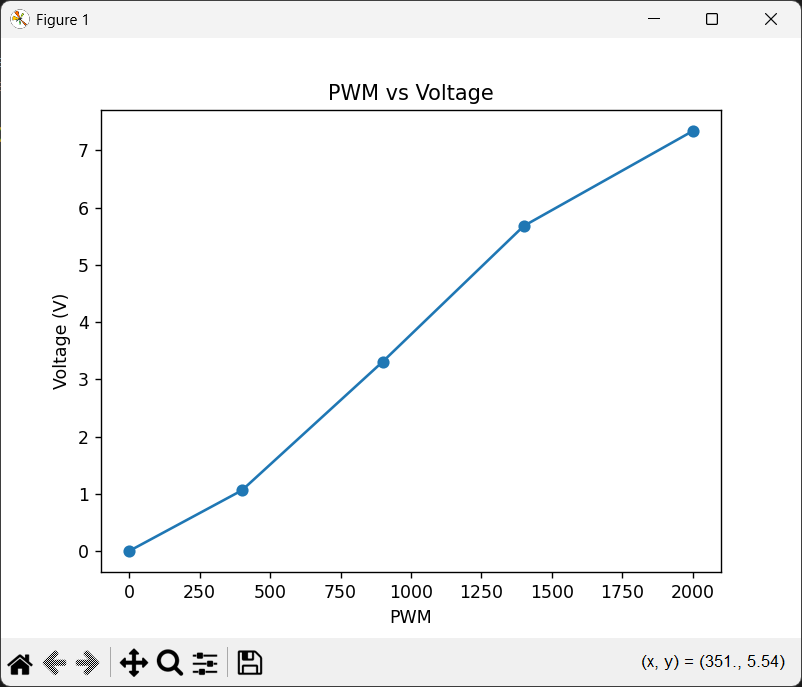

On voit que la courbe est quasiment linéaire.

***Question 8 : Lancez la simulation avec un échelon de 3,83V (pwm=1000) en entrée et observez la courbe de la vitesse de rotation du moteur. Vous devriez obtenir cette courbe :***

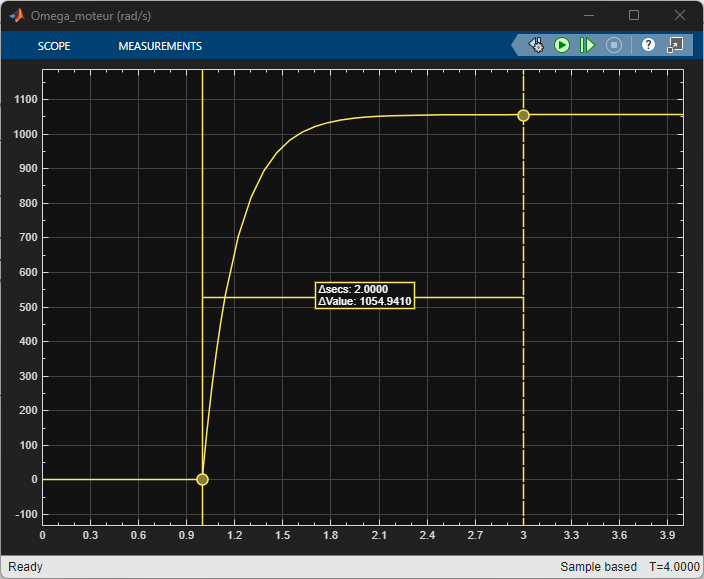

Remarque : la vitesse observée est la vitesse du moteur AVANT le réducteur en rad/s

***Question 9 : Définissez le rapport de réduction ***$r=\frac{1}{45}$*** dans le code ci-dessous :***

r = 1/45;

***Question 10 : Ajoutez un bloc "gain" dans votre modèle simulink qui permet de calculer la vitesse de la roue (APRES le réducteur) et ajoutez un deuxième bloc "gain" qui permet de convertir la vitesse en tours par minutes et observez cette vitesse à l'aide d'un bloc "scope".***

Vous devriez obtenir cette courbe :

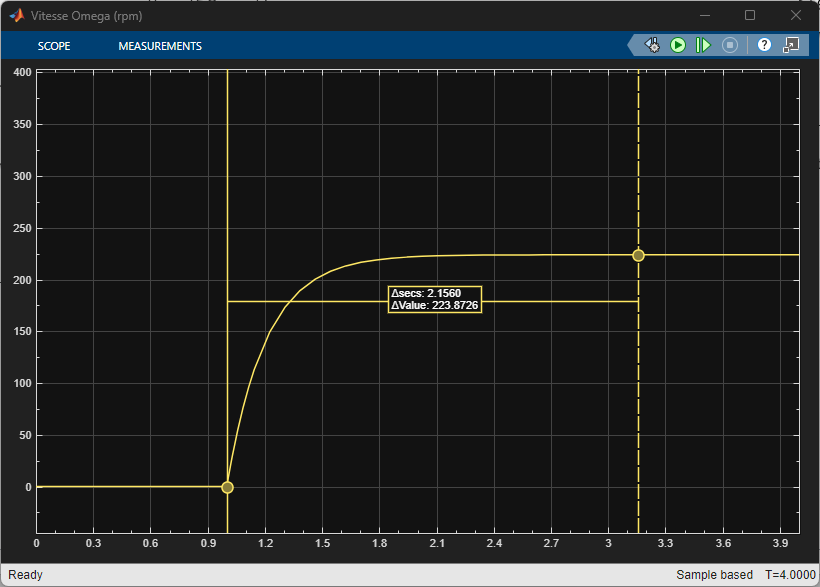

Voici la courbe obtenue sur à partir du moteur réel :

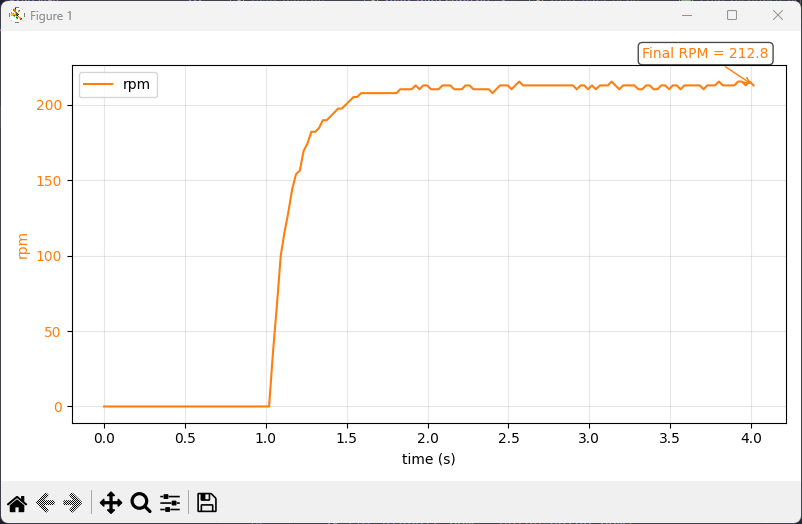

***Question 11 : Que pouvez-vous dire de la courbe obtenue après l'essai sur le vrai moteur par rapport à la simulation ?***

Maintenant nous allons ajouter le couple de frottements secs pour améliorer la précision du modèle Simulink.

Nous modélisons le frottement sec de la manière suivante : $c_f \ldotp \textrm{sign}\left(\omega_m \left(t\right)\right)$ où $\left\lbrace \begin{array}{ll}
\textrm{sign}\left(\omega_m \left(t\right)\right)=1 & \textrm{si}\;\omega_m \left(t\right)\ge 0\\
\textrm{sign}\left(\omega_m \left(t\right)\right)=-1 & \textrm{si}\;\omega_m \left(t\right)<0
\end{array}\right.$ 

***Question 12 : Ajoutez le couple de frottements secs de ***$11,4\ldotp {10}^{-5} \;N\ldotp m$ ***au modèle Simulink du MCC. Pour cela, ajoutez un bloc "gain" et un bloc et un bloc "sign" pour définir le  le couple de fottements secs et un bloc "sum" pour le soustraire au couple moteur.***

% Définir cf ici
cf = 11.4e-5;

***Question 13 : Lancez la simulation avec un échelon de 3,83V (pwm=1000) en entrée et observez la courbe de la vitesse de rotation du moteur. Vous devriez obtenir cette courbe :***

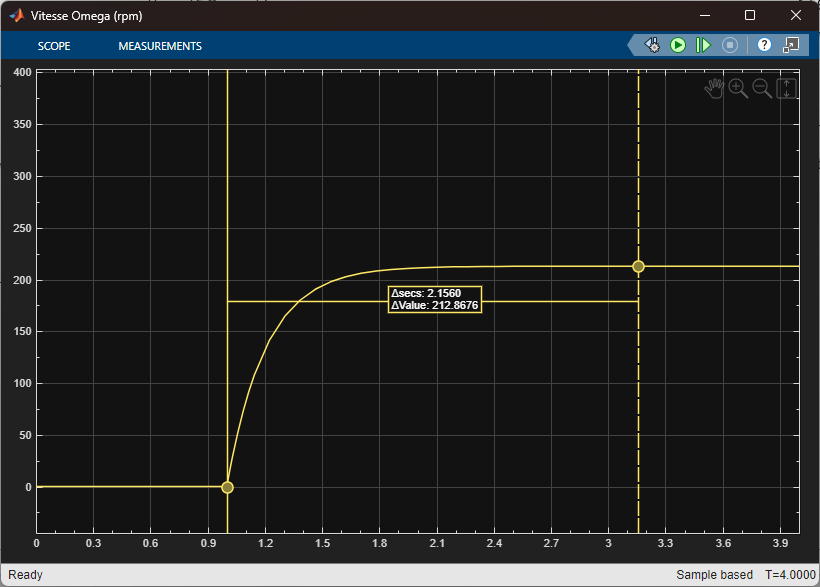

Voici la courbe obtenue sur à partir du moteur réel :

***Question 13 : Que pouvez-vous dire de la courbe obtenue après l'essai sur le vrai moteur par rapport à la simulation ?***

## ***Implémentation du correcteur PI***

### ***Mise en forme du MCC sous forme d'un sous-système***

A cette étape, nous avons un modèle du MCC qui représente fidèlement le comportement du vrai moteur. Nous alons maintenant essayer d'améliorer les performances du système en implémentant un correcteur Proprtionnel Intégral (PI). Avant cela, il faut mettre le système dans un seul bloc pour faciliter sa représentation.

***Question 14 : Supprimez le blocs "step" en entrée et le bloc "scope" en sortie comme sur cette image :***

***Question 15 : Selectionnez l'ensemble de votgre schéma blocs et cliquez sur "create subsystem" en bas a droite comme sur cette image :***

Vous devez obtenir un bloc comme ceci :

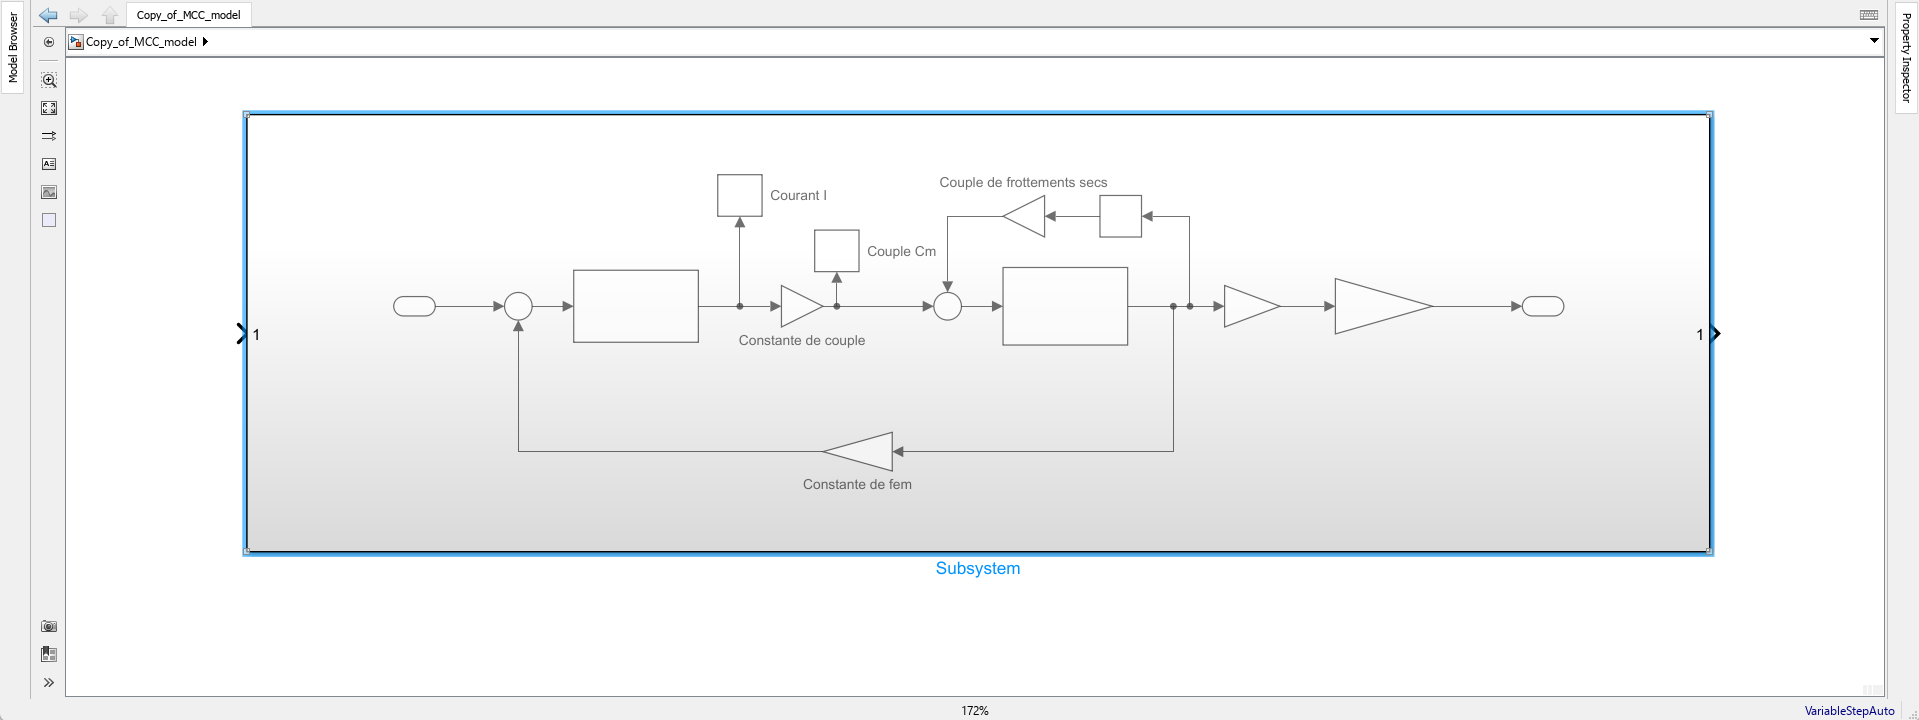

***Question 16 : Cliquez sur le nom "Subsystem" en bleu en bas du bloc et renommez le bloc "MCC".***

***Question 17: Ensuite double-cliquez sur le bloc et renommez le port in1 "U(p)" et le port out1 "Omega_roue(p)"***

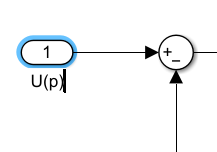

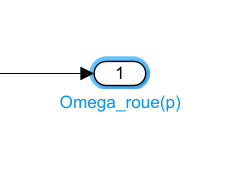

***Question 18 : Cliquez en haut à gauche sur le nom de votre fichier simulink pour voir sortir à l'éxtérieur du sous-système MCC que vous avez créé à la question 17***

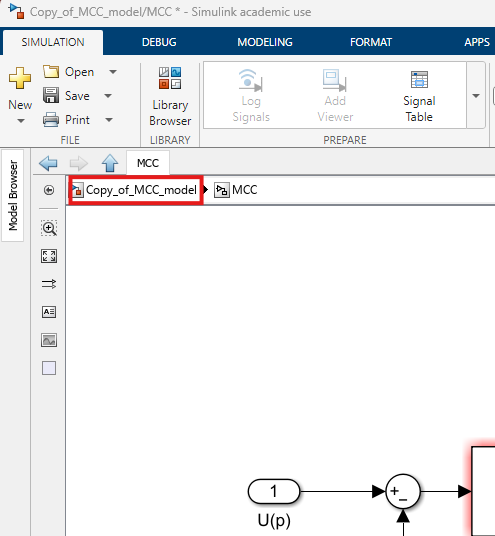

Vous devriez obtenir un écran similaire à cette image :

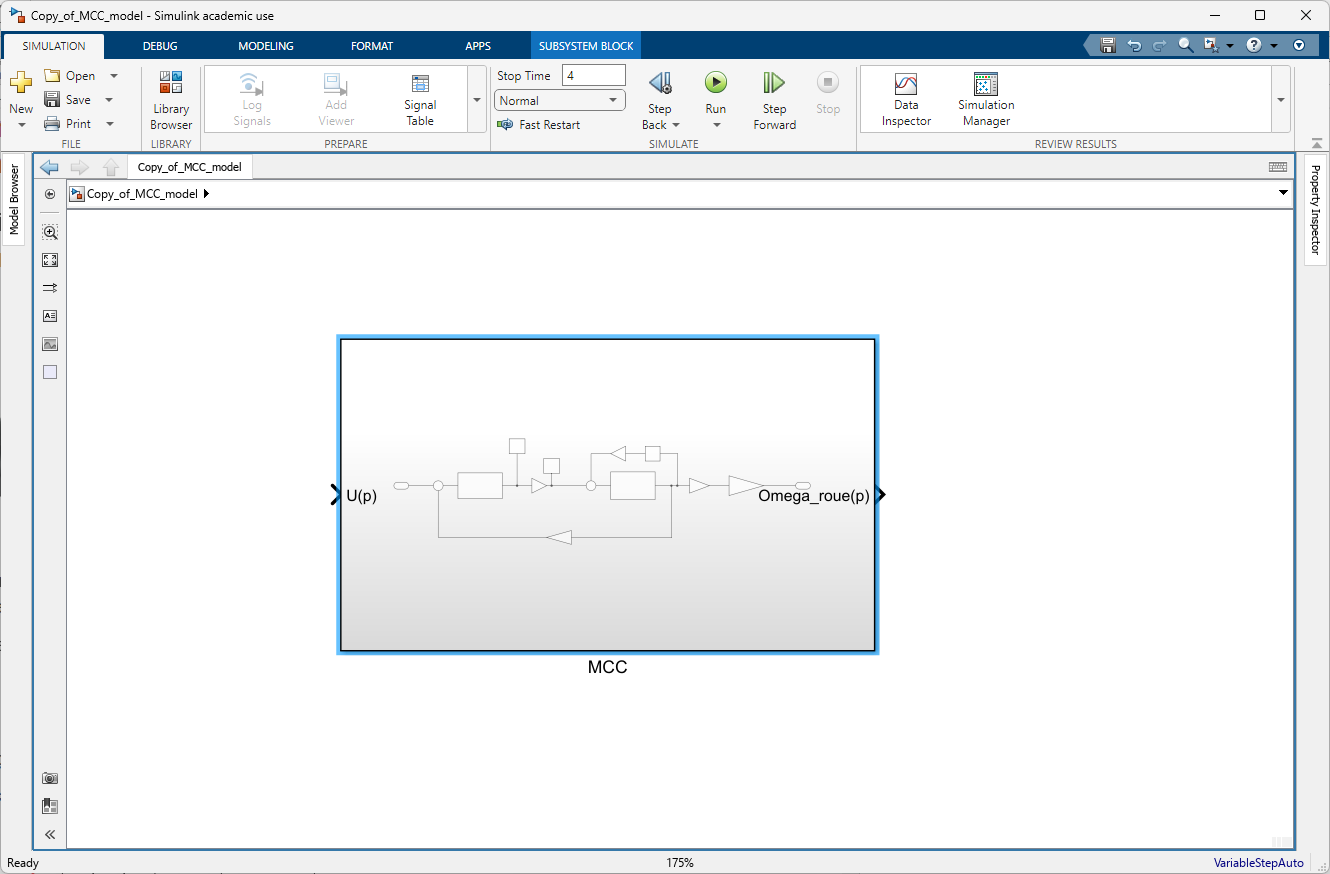

Maintenant, le MCC est sous forme d'un seul bloc "sous-système" défini par sa fonction de transfert en boucle fermée (FTBF) calculée automatiquement par Simulink.

A ce stade, il ne reste plus qu'a implémenter le correcteur PI.

Commençons par implémenter un correcteur proportionnel.

### Implémentation d'un correcteur proportionnel

***Question 19 : Ouvrez le fichier "MCC_P.slx". Copiez-Collez le bloc MCC que vous avez créé dans la question précédente dans le fichier "MCC_P.slx"et connectez le aux flèches rouges.***

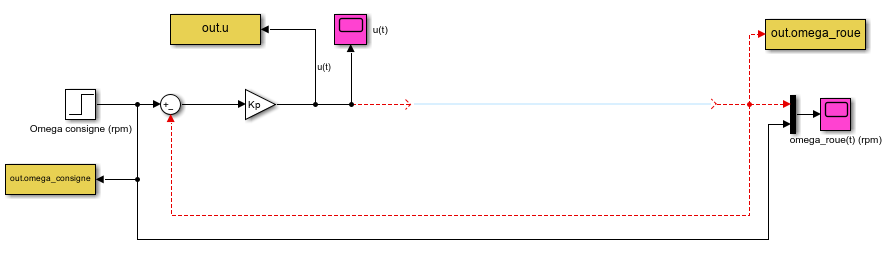

Voici le schéma que vous devriez obtenir :

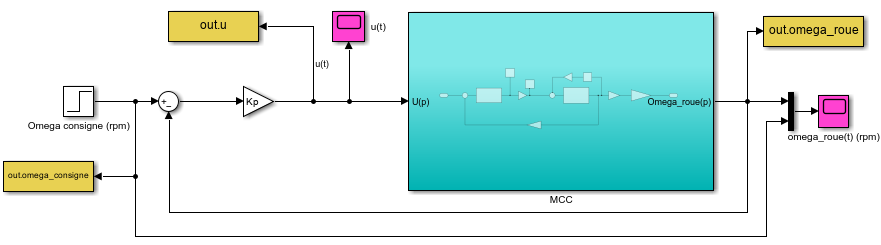

On trace la force electromotrice e(t) (commande) générée pour un échelon de vitesse de 216 tours par minute en entrée pour différentes valeurs de $K_p$.

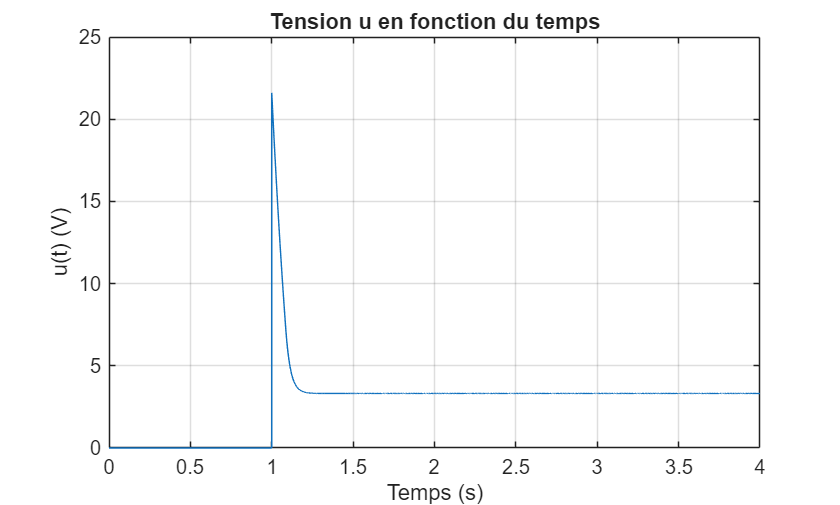

Kp=0.1;
out = sim("MCC_P.slx"); % lancement de la simulation et récupération des signaux connectés aux blocs jaunes

% Extraire les données de la simulation
time = out.get('tout'); % temps de simulation
u = out.get('u');       % signal de tension

% Tracer la figure de u en fonction du temps
figure;
plot(time, u);
xlabel('Temps (s)');
ylabel('u(t) (V)');
title('Tension u en fonction du temps');
grid on;

***Question 20 : Pour ***$K_p =0,1$***, qu'observez vous ?***

On observe un pic de 20V.

***Question 21 : Dans le fichier "MCC_P.slx", ajoutez une saturation entre +7,34V et -7,34V pour limiter la tension aux bornes du moteur. Pour ce faire ajoutez un bloc "saturation"  ainsi qu'un bloc "To Workspace" qui renvoie un vecteur "u_sat" sous forme d'array comme sur l'image suivante.***

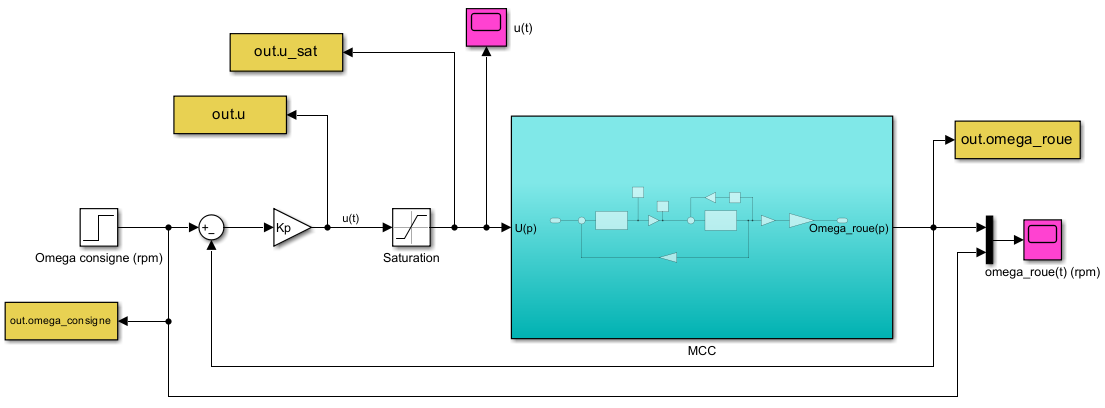

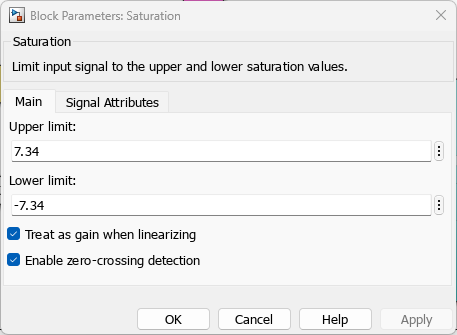

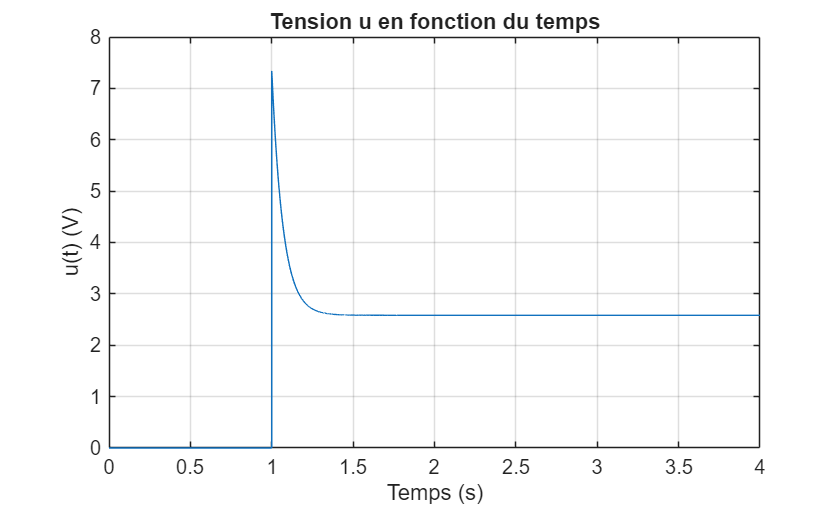

Kp=0.034;
out = sim("MCC_P.slx"); % lancement de la simulation et récupération des signaux connectés aux blocs jaunes

% Extraire les données de la simulation
time = out.get('tout'); % temps de simulation
u = out.get('u_sat');       % signal de tension

% Tracer la figure de u en fonction du temps
figure;
plot(time, u);
xlabel('Temps (s)');
ylabel('u(t) (V)');
title('Tension u en fonction du temps');
grid on;

***Question 22 : Qu'observez-vous sur la courbe de la tension de commande lorsque ***$K_p =0,1$ ***? ***

Le signal u(t) est saturé au début.

***Question 23 : Choisissez un gain ***$K_p$*** le plus grand possible tel que le signal de commande ***$u\left(t\right)$*** ne soit pas saturé.***


$$K_p =0,034$$


Maintenant on cherche a observer l'influence du gain $K_p$ sur les performances du système. Pour cela, on trace la réponse du système en fonction de $K_{p\ldotp }$

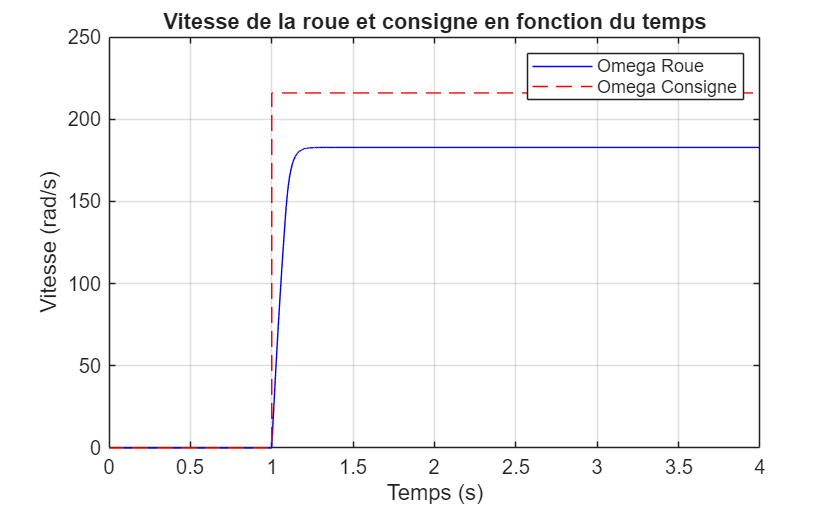

Kp=0.1;
out = sim("MCC_P.slx"); % lancement de la simulation et récupération des signaux connectés aux blocs jaunes

% Extraire les données de la simulation pour omega_roue et omega_consigne
time = out.get('tout'); % temps de simulation
omega_roue = out.get('omega_roue');       % vitesse de la roue
omega_consigne = out.get('omega_consigne'); % vitesse consignée

% Tracer omega_roue et omega_consigne en fonction du temps
figure;
plot(time, omega_roue, 'b', 'DisplayName', 'Omega Roue');
hold on;
plot(time, omega_consigne, 'r--', 'DisplayName', 'Omega Consigne');
xlabel('Temps (s)');
ylabel('Vitesse (rad/s)');
title('Vitesse de la roue et consigne en fonction du temps');
legend show;
grid on;

***Question 23 : Qu'observez-vous lorsque ***$K_p$ ***vaut la valeur que vous avez trouvée à la question précédente ?***

L'erreur statique est très grande.

### Implémentation du correcteur PI

***Question 24 : Ouvrez le fichier "MCC_PI.slx" et copiez votre bloc "MCC" dans l'espace vide***

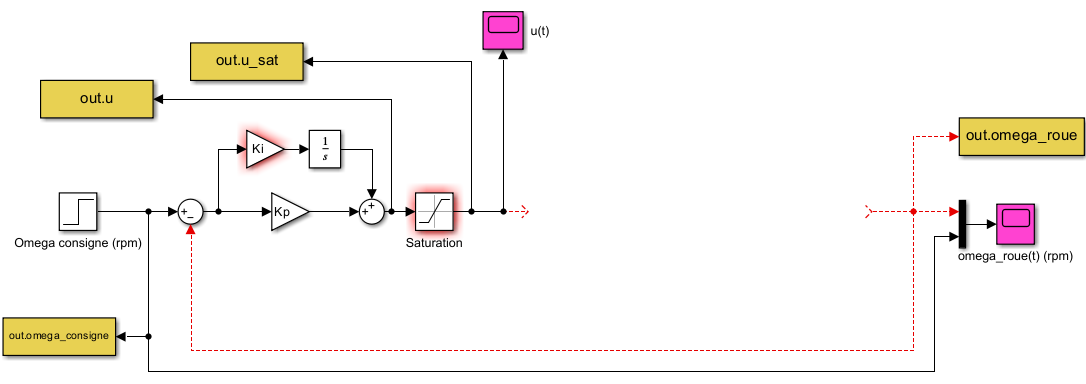

Voici le schéma que vous devriez obtenir :

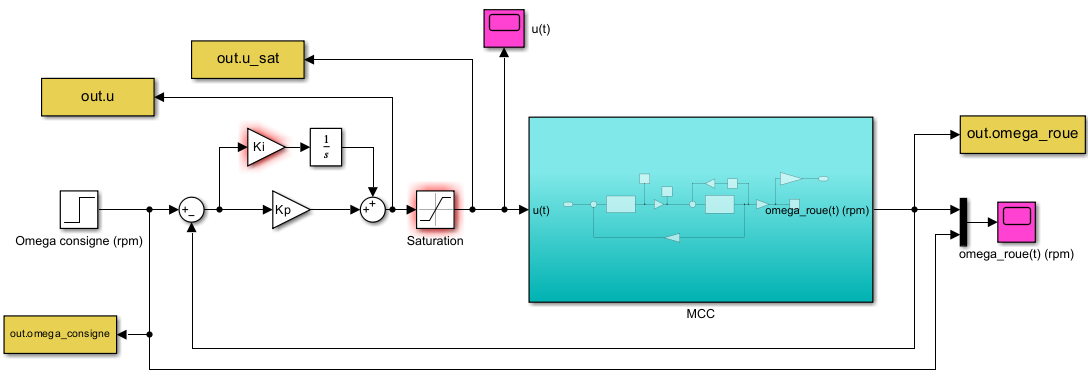

***Question 25 : Réglez ***$K_p$*** sur la valeur que vous avez trouvée à la question 23. Ensuite, trouvez une valeur de ***$K_i$*** telle que le dépassement soit inférieur à 10% et que le temps de réponse du système soit inféreur à 1,2s ***

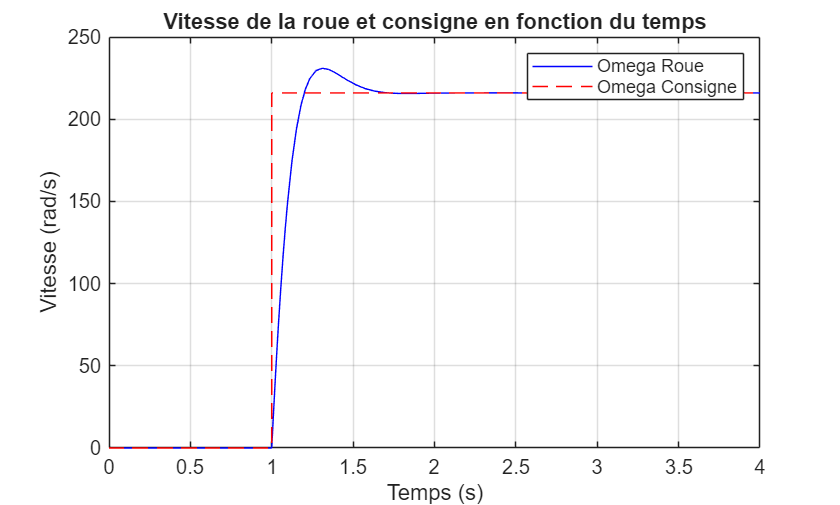

Kp=0.034;
Ki=0.32;
out = sim("MCC_PI.slx"); % lancement de la simulation et récupération des signaux connectés aux blocs jaunes

% Extraire les données de la simulation pour omega_roue et omega_consigne
time = out.get('tout'); % temps de simulation
omega_roue = out.get('omega_roue');       % vitesse de la roue
omega_consigne = out.get('omega_consigne'); % vitesse consignée

% Tracer omega_roue et omega_consigne en fonction du temps
figure;
plot(time, omega_roue, 'b', 'DisplayName', 'Omega Roue');
hold on;
plot(time, omega_consigne, 'r--', 'DisplayName', 'Omega Consigne');
xlabel('Temps (s)');
ylabel('Vitesse (rad/s)');
title('Vitesse de la roue et consigne en fonction du temps');
legend show;
grid on;

% Calculer le temps de réponse
response_time = time(find(omega_roue >= 0.95 * max(omega_consigne), 1, 'first'));
fprintf('Le temps de réponse est de %.4f secondes.\n', response_time);

Le temps de réponse est de 1.1788 secondes.


% Calculer le dépassement
overshoot = (max(omega_roue) - max(omega_consigne)) / max(omega_consigne) * 100;
fprintf('Le dépassement est de %.2f%%.\n', overshoot);

Le dépassement est de 6.94%.
